# Tutorial 9 - Simulate a cylindrical cell

## Introduction

In this tutorial, we simulate a multilayer pouch cell. We use the same material property as in the other tutorials

jsonstruct_material = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

Next, we load and parse a json file where we have chosen some parameters for the multilayer pouch domain. Note that all the parameters are described in a json schema, see [Geometry.schema.json](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonSchemas/Geometry.schema.json), even if the simplest way to proceed is to start with an example, in this case given by [4680-geometry.json](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonDataFiles/4680-geometry.json).

jsonfilename = 'Examples/JsonDataFiles/4680-geometry.json';
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We change some parameters to get a smaller model and simulation time.

jsonstruct_geometry.Geometry.outerRadius = jsonstruct_geometry.Geometry.innerRadius + 4*milli*meter;
jsonstruct_geometry.Geometry.numberOfDiscreteCellsVertical = 2;
jsonstruct_geometry.Geometry.numberOfDiscreteCellsAngular  = 20;

We use [FlatStructViewer.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonUtils/FlatStructViewer.m) to flatten the json structure and print it to screen.

fsv = flattenStruct(jsonstruct_geometry);

                              parameter name                                   parameter value     
    __________________________________________________________________    _________________________
    {'include_current_collectors'                                    }    {[                    1]}
    {'Geometry.case'                                                 }    {'jellyRoll'            }
    {'Geometry.innerRadius'                                          }    {[    0.002000000000000]}
    {'Geometry.outerRadius'                                          }    {[    0.006000000000000]}
    {'Geometry.height'                                               }    {[    0.070000000000000]}
    {'Geometry.verticalRefinementParameter'                          }    {[                    3]}
    {'Geometry.numberOfDiscreteCellsAngular'                         }    {[                   20]}
    {'Geometry.numberOfDiscreteC

fsv.print();

                              parameter name                                   parameter value     
    __________________________________________________________________    _________________________
    {'include_current_collectors'                                    }    {[                    1]}
    {'Geometry.case'                                                 }    {'jellyRoll'            }
    {'Geometry.innerRadius'                                          }    {[    0.002000000000000]}
    {'Geometry.outerRadius'                                          }    {[    0.006000000000000]}
    {'Geometry.height'                                               }    {[    0.070000000000000]}
    {'Geometry.verticalRefinementParameter'                          }    {[                    3]}
    {'Geometry.numberOfDiscreteCellsAngular'                         }    {[                   20]}
    {'Geometry.numberOfDiscreteC

We load and parse the control protocol

jsonfilename = fullfile('Examples', 'jsondatafiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);

We load and parse the simulation settings. This is optional. Typically, reasonable choices are made by default.

jsonfilename = fullfile('Examples', 'jsondatafiles', 'simulation_parameters.json');
jsonstruct_simparams = parseBattmoJson(jsonfilename);

Now, we can merge these parameter definitions into a single parameter set to obtain a jsonstruct that has all the input needed by the simulator.

jsonstruct = mergeStructs({jsonstruct_geometry , ...
    jsonstruct_material , ...
    jsonstruct_control  , ...
    jsonstruct_simparams}, 'warn', false);

## Setup the model for inspection

When we run the simulation using function [runBattery.m](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonInput/runBattery.m), the model is setup. In the case where we want to setup the model for inspection, prior to simulation, we can use the function [setupModelFromJson.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonUtils/setupModelFromJson.m)

model = setupModelFromJson(jsonstruct);

We use the [plotBatteryGrid.m](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/Visualization/plotBatteryGrid.m) function to show the grid

plotBatteryGrid(model)

ans = struct with fields:
    figure: [1×1 Figure]
    legend: [1×1 Legend]

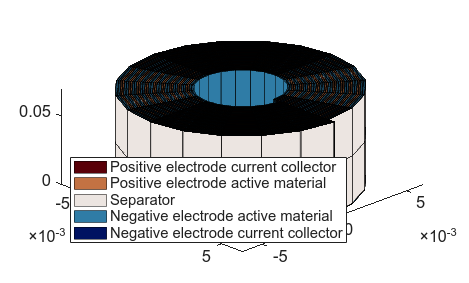

% make the axis tight and set the camera viewing angle
axis tight
view(45,45)

## Run the simulation

output = runBattery(jsonstruct);

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

## Visualize the Results

extract the time and voltage quantities

states = output.states;

time    = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);

We plot the discharge curves together in a new figure

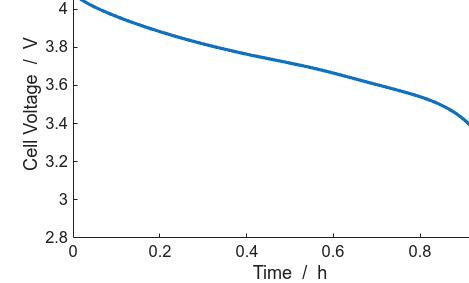

figure();
plot((time/hour), voltage, '-', 'linewidth', 3)
xlabel('Time  /  h')
ylabel('Cell Voltage  /  V')
title('Voltage');

For a given time step, we plot the concentration on the grid in the negative and positive electrodes.

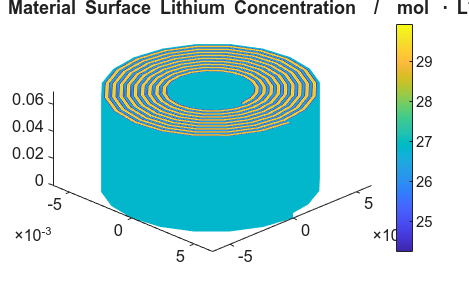

% Set the timestep we want to visualize
timestep = 20;

% get the state of the simulation at the given timestep
state = states{timestep};

% create a new figure
figure()

% plot the surface concentration of lithium in the negative electrode active material
plotCellData(model.NegativeElectrode.Coating.grid, ...
    state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre), ...
    'edgecolor', 'none');

% plot the surface concentration of lithium in the positive electrode active material
plotCellData(model.PositiveElectrode.Coating.grid, ...
    state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre), ...
    'edgecolor', 'none')

title('Active Material Surface Lithium Concentration  /  mol \cdot L^{-1}');
% add a colorbar
colorbar()
view(45,45)


%{
Copyright 2021-2026 SINTEF Industry, Sustainable Energy Technology
and SINTEF Digital, Mathematics & Cybernetics.

This file is part of The Battery Modeling Toolbox BattMo

BattMo is free software: you can redistribute it and/or modify
it under the terms of the GNU General Public License as published by
the Free Software Foundation, either version 3 of the License, or
(at your option) any later version.

BattMo is distributed in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
GNU General Public License for more details.

You should have received a copy of the GNU General Public License
along with BattMo.  If not, see <http://www.gnu.org/licenses/>.
%}